# Intake: Throttle Mass Flow

Given throttle command, compute the intake manifold pressure, which is required by the cylinder model.

## Throttle Air Mass Flow

syms G_thr p_d p_u T_u S_thr pr_cr pr_lam k_1 k_2 k_a k_b k_c kappa R_gas

Main function - throttle mass flow rate

% G_thr is in [kg/s] when S_thr is in [m^2]
eq_thr = ...
    G_thr == piecewise( ...
        p_d/p_u > pr_lam , ...
            S_thr*k_a*(p_u - p_d)/sqrt(T_u) , ...
        p_d/p_u > pr_cr , ...
            S_thr*p_u*sqrt( k_b*( (p_d/p_u)^k_2 - (p_d/p_u)^k_1 ) )/sqrt(T_u) , ...
            S_thr*p_u*k_c/sqrt(T_u) )

$$eq\_thr = G_{\mathrm{thr}}=\left\{ \begin{array}{cl} -\frac{S_{\mathrm{thr}}\,k_{a}\,\left(p_{d}-p_{u}\right)}{\sqrt{T_{u}}} & \text{ if }{\mathrm{pr}}_{\mathrm{lam}}<\frac{p_{d}}{p_{u}}\\ \frac{S_{\mathrm{thr}}\,p_{u}\,\sqrt{-k_{b}\,\left({\left(\frac{p_{d}}{p_{u}}\right)}^{k_{1}}-{\left(\frac{p_{d}}{p_{u}}\right)}^{k_{2}}\right)}}{\sqrt{T_{u}}} & \text{ if }{\mathrm{pr}}_{\mathrm{cr}}<\frac{p_{d}}{p_{u}}\\ \frac{S_{\mathrm{thr}}\,k_{c}\,p_{u}}{\sqrt{T_{u}}} & \mathrm{otherwise} \end{array}\right.$$

Model parameters

% constants
clear valfcn  % valfcn = valuation function
valfcn(1) = kappa == 1.4;  % '1' .. dry air
valfcn(2) = R_gas == 286;  % 'J/kg/K' .. dry air
valfcn(3) = pr_lam == 0.999;  % '1' .. laminar flow threshold (arbitrary)
valfcn(4) = p_u == 101325;  % 'Pa'
valfcn(5) = T_u == 273.15+25;  % 'K'
valfcn

$$valfcn = \left(\begin{array}{ccccc} \kappa =\frac{7}{5} & R_{\mathrm{gas}}=286 & {\mathrm{pr}}_{\mathrm{lam}}=\frac{999}{1000} & p_{u}=101325 & T_{u}=\frac{5963}{20} \end{array}\right)$$

Derived constants

% derived constants
expr = containers.Map();
expr('pr_cr') = (2/(kappa + 1))^(kappa/(kappa - 1));
expr('k_1') = (kappa + 1)/kappa;
expr('k_2') = 2/kappa;
expr('k_a') = sqrt(k_b*(pr_lam^k_2 - pr_lam^k_1))/(1 - pr_lam);  % 'sqrt(K*kg/J)'
expr('k_b') = 2*kappa/(R_gas*(kappa - 1));  % 'K*kg/J'
expr('k_c') = sqrt( (kappa/R_gas)*pr_cr^k_1 );  % 'sqrt(K*kg/J)'

% applyvf = apply valuation function
applyvf = @(s,vf) sym(s) == subs(expr(s), lhs(vf), rhs(vf));

dispeqn = @(eqn) fprintf('%s == %g\n', lhs(eqn), double(rhs(eqn)));

valfcn(end+1) = applyvf('pr_cr', valfcn);
dispeqn(valfcn(end))

pr_cr == 0.528282


valfcn(end+1) = applyvf('k_1', valfcn);
dispeqn(valfcn(end))

k_1 == 1.71429


valfcn(end+1) = applyvf('k_2', valfcn);
dispeqn(valfcn(end))

k_2 == 1.42857


valfcn(end+1) = applyvf('k_b', valfcn);
dispeqn(valfcn(end))

k_b == 0.0244755


valfcn(end+1) = applyvf('k_a', valfcn);
dispeqn(valfcn(end))

k_a == 2.64301


valfcn(end+1) = applyvf('k_c', valfcn);
dispeqn(valfcn(end))

k_c == 0.040489


Throttle mass flow rate function

% don't know how to change the display format of numeric values here...
result = subs( eq_thr ,lhs(valfcn),rhs(valfcn))

$$result = G_{\mathrm{thr}}=\left\{ \begin{array}{cl} -\frac{1000\,\sqrt{20}\,\sqrt{5963}\,S_{\mathrm{thr}}\,\sqrt{\frac{6993\,999^{3/7}\,1000^{4/7}}{286000000}-\frac{6993\,999^{5/7}\,1000^{2/7}}{286000000}}\,\left(p_{d}-101325\right)}{5963} & \text{ if }\frac{4048947}{40}<p_{d}\\ \frac{101325\,\sqrt{20}\,\sqrt{5963}\,S_{\mathrm{thr}}\,\sqrt{\frac{7\,{\left(\frac{p_{d}}{101325}\right)}^{10/7}}{286}-\frac{7\,{\left(\frac{p_{d}}{101325}\right)}^{12/7}}{286}}}{5963} & \text{ if }\frac{4221875\,\sqrt{5}\,\sqrt{6}}{432}<p_{d}\\ \frac{101325\,\sqrt{20}\,\sqrt{5963}\,S_{\mathrm{thr}}\,\sqrt{\frac{7\,{\left(\frac{125\,\sqrt{5}\,\sqrt{6}}{1296}\right)}^{12/7}}{1430}}}{5963} & \mathrm{otherwise} \end{array}\right.$$

Plot

% Assume S_thr = 10 cm^2 = 0.001 m^2
f = rhs(subs(result, S_thr, 0.001))

$$f = \left\{ \begin{array}{cl} -\frac{\sqrt{20}\,\sqrt{5963}\,\sqrt{\frac{6993\,999^{3/7}\,1000^{4/7}}{286000000}-\frac{6993\,999^{5/7}\,1000^{2/7}}{286000000}}\,\left(p_{d}-101325\right)}{5963} & \text{ if }\frac{4048947}{40}<p_{d}\\ \frac{4053\,\sqrt{20}\,\sqrt{5963}\,\sqrt{\frac{7\,{\left(\frac{p_{d}}{101325}\right)}^{10/7}}{286}-\frac{7\,{\left(\frac{p_{d}}{101325}\right)}^{12/7}}{286}}}{238520} & \text{ if }\frac{4221875\,\sqrt{5}\,\sqrt{6}}{432}<p_{d}\\ \frac{4053\,\sqrt{20}\,\sqrt{5963}\,\sqrt{\frac{7\,{\left(\frac{125\,\sqrt{5}\,\sqrt{6}}{1296}\right)}^{12/7}}{1430}}}{238520} & \mathrm{otherwise} \end{array}\right.$$

% Check that there is only one variable;
vars = symvar(f)

$$vars = p_{d}$$

numel(vars)

ans = 1

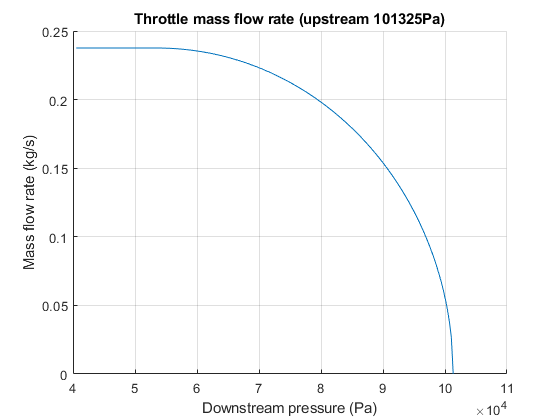

% Create a symbolic function
f = symfun(f, p_d);

x = linspace(101325*0.4, 101325*1, 200);
y = f(x);
figure
hold on
plot(x, y)
grid on
xlabel('Downstream pressure (Pa)')
ylabel('Mass flow rate (kg/s)')
title('Throttle mass flow rate (upstream 101325Pa)')